% add Psort_read_psort() function to path
addpath('C:\Users\baozi\OneDrive - Johns Hopkins\Documents\JHU\CullenLab_new\CSsorting\osfstorage-archive\Psort_matlab_codes');

filename = 'C:\Users\baozi\OneDrive - Johns Hopkins\Documents\JHU\CullenLab_new\CSsorting\osfstorage-archive\macaque_3min_psort_data\P03_2_pre_A_sorted_MAF.psort';
psortDataBase = Psort_read_psort(filename);

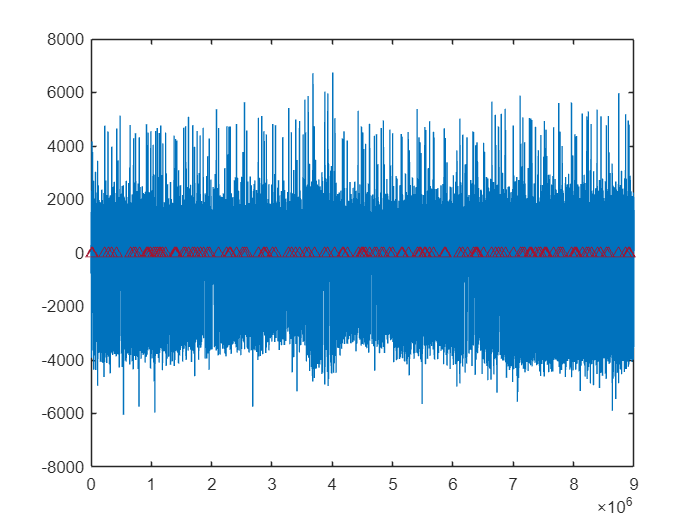

fs = psortDataBase.topLevel_data.sample_rate;
fs_ms = fs/1000;
pre_ms = 1;
post_ms = 10;

ss_index = find(psortDataBase.topLevel_data.ss_index);
cs_index = find(psortDataBase.topLevel_data.cs_index);

figure;
plot(psortDataBase.topLevel_data.ch_data);
hold on;
scatter(cs_index,zeros(length(cs_index)),'^');

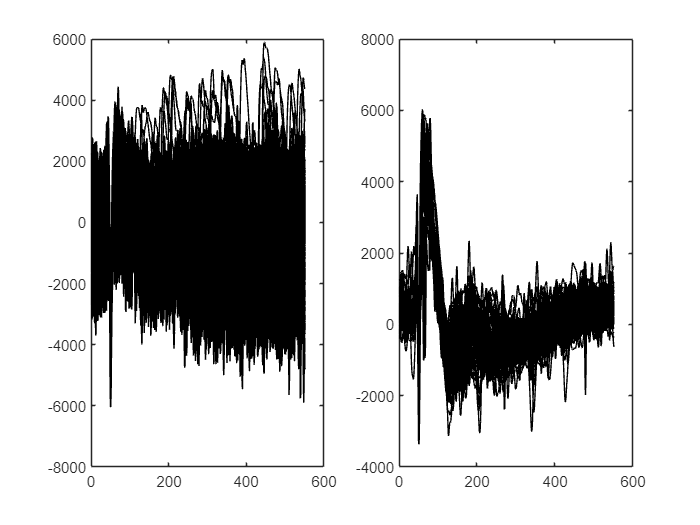


figure;
subplot(121);
for i = 1:length(ss_index)
    if ss_index(i)-pre_ms*fs_ms < 1
        continue
    end
    if ss_index(i)+post_ms*fs_ms > length(psortDataBase.topLevel_data.ch_data)
        continue
    end
    plot(psortDataBase.topLevel_data.ch_data(ss_index(i)-pre_ms*fs_ms:ss_index(i)+post_ms*fs_ms),'k');
    hold on;
end

subplot(122);
for i = 1:length(cs_index)
    if cs_index(i)-pre_ms*fs_ms < 1
        continue
    end
    if cs_index(i)+post_ms*fs_ms > length(psortDataBase.topLevel_data.ch_data)
        continue
    end
    plot(psortDataBase.topLevel_data.ch_data(cs_index(i)-pre_ms*fs_ms:cs_index(i)+post_ms*fs_ms),'k');
    hold on;
end

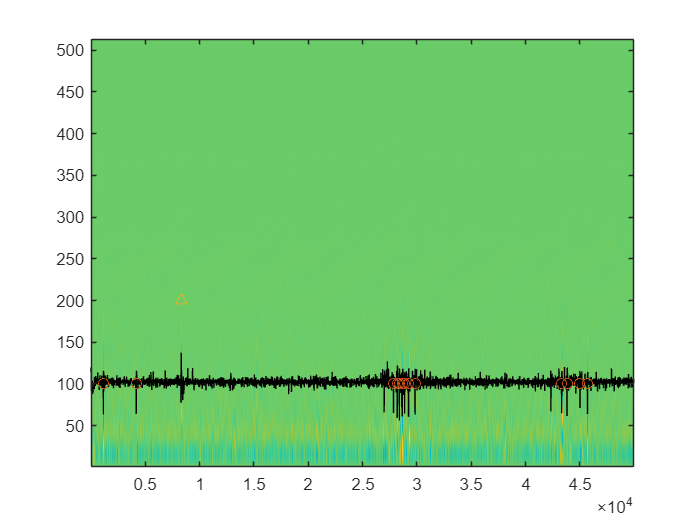

% stft
WindowLength = 32;
OverlapLength = WindowLength-1;
FFTLength = 1024;

start_ms = floor(cs_index(1)/fs_ms);
end_ms = start_ms+1000;

[spec,f,t] = stft(psortDataBase.topLevel_data.ch_data(fs_ms*start_ms:fs_ms*end_ms),fs,...
    Window=hann(WindowLength,'periodic'),OverlapLength=OverlapLength,...
    FFTLength=FFTLength,FrequencyRange="onesided");
spec = imag(spec);

figure;
imagesc(spec);
hold on;
set(gca,'YDir','normal');
plot(100+psortDataBase.topLevel_data.ch_data(fs_ms*start_ms+ceil(WindowLength/2+1):fs_ms*end_ms)/100,'k');
scatter(ss_index-ceil(WindowLength/2+1)-double(start_ms*fs_ms),ones(length(ss_index),1)*100,'o');
scatter(cs_index-ceil(WindowLength/2+1)-double(start_ms*fs_ms),ones(length(cs_index),1)*200,'^');